# FIELD CALIBRATION

Script for field calibration using a sample of NaC60. There are two different methods, which lead to similar results (around 1e-4 agreement between the results): 1. Using the function pepperFieldOffset written by Jannik 2. Obtaining the g-value from esfit and from there calculating the field offset

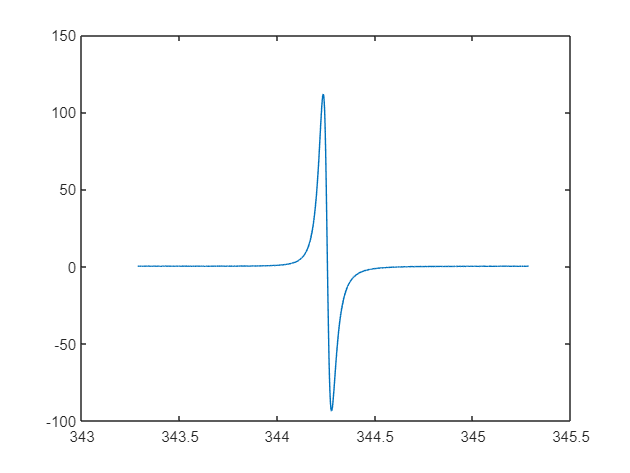

clear, clc, close all

% Import
[data.B, data.spc, Params] = eprload('D:\Profile\qse\Files\_EDMRoC pinSC\20210617\017_BDPA_100kHz_0p15G_1scan.DTA');

% Convert B to mT
data.B = data.B./10;

figure()
plot(data.B, data.spc)

## METHOD 1. pepperFieldOffset

esfit with the function pepperFieldOffset returns the value of the field offset directly. When using this method the g-value is fixed to the value of the literature. System

Sys.S = 1/2;
Sys.g = 2.003; % Value from the literature
Sys.lw = [0.0 0.2]; % mT [Gaussian Lorentzian]
Sys.FieldOffset = 0.1; % mT

% Parameter ranges
Vary.lw = [0. 0.15];
Vary.FieldOffset = 0.05;

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(data.B) max(data.B)]; % Accepts only [Binit Bfin] and not [Bcenter width]

% esfit(data.spc, @pepperFieldOffset, {Sys, Exp}, {Vary});

fit = esfit(data.spc, @pepperFieldOffset, {Sys, Exp}, {Vary});

-- esfit ------------------------------------------------
Data size:                [1024, 1]
Model function name:      pepperFieldOffset
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.40517e+01   edge 1.00000e-01   initial simplex
iteration   2: value 1.40517e+01   edge 3.00000e-02   reflection
iteration   3: value 1.12138e+01   edge 4.50000e-02   expansion
iteration   4: value 1.12138e+01   edge 4.50000e-02   reflection
iteration   5: value 1.11483e+01   edge 4.50000e-02   reflection
iteration   6: value 4.32109e+00   edge 8.25000e-02   expansion
iteration   7: value 4.32109e+00   edge 6.75000e-02   reflection
iteration   8: value 4.32109e+00   edge 2.25000e-02   reflection
iteration   9: value 4.32109e+00   edge 2.25000e-02   contraction inside
iteration

## Plot (not fancy)

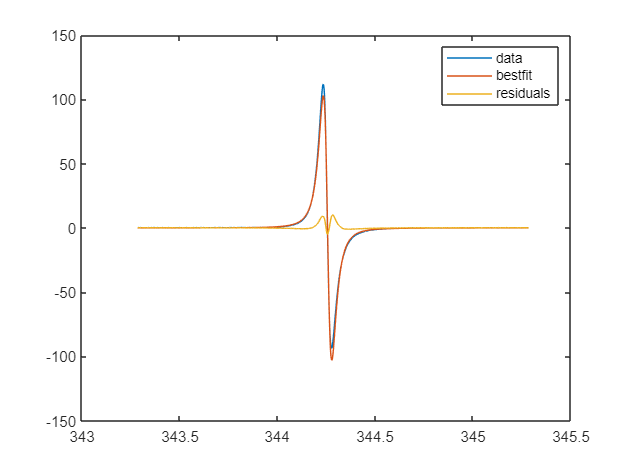

figure()
plot(data.B, data.spc);
hold on
% Same normalization as data.spc because fit.spc comes out of esfit
plot(data.B, fit.fit); 
plot(data.B, data.spc - fit.fit)
legend('data', 'bestfit', 'residuals')

## METHOD 2. Difference of g-values

%{
% In this method the g-value is obtained from esfit and then the difference
% between this value and the one from the literature is used to get the
% magnetic field offset.
% System
Sys.S = 3/2;
Sys.g = 2.00211;
Sys.A = 15.9173; % MHz
Sys.lw = [0.009 0.0199]; % mT [Gaussian Lorentzian]
Sys.Nucs = 'N';

% Parameter ranges
Vary.g = 0.002;
Vary.lw = [0.01 0.01];

% Parameters of the experiment
Exp.mwFreq = Params.MWFQ*1e-09; % GHz
Exp.Range = [min(data.B)/10 max(data.B)/10]; % Accepts only [Binit Bfin] and not [Bcenter width]

% Sys2 is to be used if there is another signal, not belonging to NaC60, to 
% be fitted. Fitting this signal is not essential nor interesting and 
% can definitely be avoided.
%{
Sys2.S = 1/2;
Sys2.g = 2.00241;
Sys2.lw = [0.080 0.1597];
Sys2.weight = 63.49;

Vary2.g = 0.001;
Vary2.lw = [0.05 0.05];
Vary2.weight = 10;
%}

esfit('pepper', data.spc, Sys, Vary,  Exp);
% esfit('pepper', data.spc, {Sys, Sys2}, {Vary, Vary2},  Exp);

## ´

Manually save the best-fit parameters using the GUI (usual name of the structure is: fit1) and store it in SysFit2

SysFit2 = ;

bestfit2 = pepperFieldOffset(SysFit2, Exp);

figure()
plot(data.B, data.spc / ((max(data.spc) - min(data.spc))));
hold on
plot(data.B, bestfit2 / ((max(bestfit2) - min(bestfit2))));
legend('data', 'bestfit')

## Field Offset

B_meas = (h * nu) / (mu * g_meas) B_lit = (h * nu) / (mu * g_lit) dB = B_meas - B_lit = (h * nu / mu) * (1 / g_meas - 1 / g_lit)

FieldOffset2 = planck * Params.MWFQ / bmagn * ...
    (1 / SysFit2.g - 1 / Sys1.g); %mT
%}